# **RT-QIBC analysis**

**YFP2: EdU**

**FarRed1: geminin IF**

**FarRed2: Cdt1 IF**

**POI(:,3): CRL4Cdt2 activation time**

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
        'cells',2:3,2:10,1:6,[0 0 0]; %1      
    'ctrl',2:3,11,1:6,[0 0 0]; %1      
};


load([dataDir filesep 'C204_data.mat'],'S');
% S = loadData(conditions, dataDir);
framesPerHr = 60/10;
frameDrugAdded = 0;
frameEdU = 0;
timeStart = 3.5;
folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;


times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};


**Set thresholds**

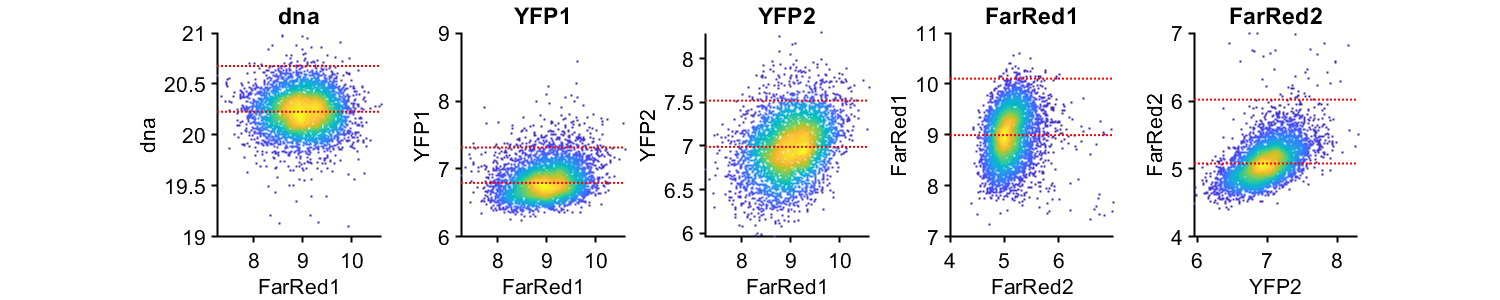


%% Set gates time after mitosis
cond=1;
gate = struct();
gates = {'dna','YFP1','YFP2','FarRed1','FarRed2'};
plotting = {'FarRed1','FarRed1','FarRed1','FarRed2','YFP2'};
prctiles = {[50 99], [50 95],[50 95],[50 99],[50 99]};

figure('pos',[0 0 length(gates)*300 300 ])

for i = 1:length(gates)
    inds = S(cond).POI_time(:,1) <= 2 & S(cond).POI_time(:,1) > 1 & S(cond).dna < 2^21 & S(cond).FarRed2 < 2^7;
    ydata = S(cond).(gates{i})(inds,:);
    xdata = S(cond).(plotting{i})(inds,:);
    
    gate.([gates{i} '_G1']) = prctile(ydata, prctiles{i});
    
    subplot(1,length(gates),i)
    dscatter(log2(xdata),log2(ydata));
    hline( log2(gate.([gates{i} '_G1'])))
    ylabel(gates{i});
    xlabel(plotting{i});
    title(gates{i});
%     
%     if strcmp(gates{i},'FarRed1')
%         g1cellsedu = ydata;
%     end
%     if strcmp(gates{i},'YFP2')
%         g1cellsgem = ydata;
%     end
%         if strcmp(gates{i},'YFP5')
%         g1cellscyc = ydata;
%     end
end

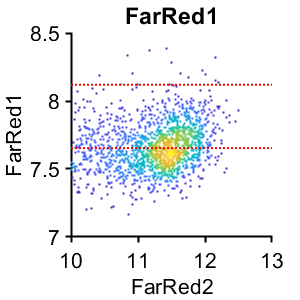



%% set S phase gates
cond=1;
gates = {'FarRed1'};
plotting = {'FarRed2'};
prctiles = {[50 99]};

figure('pos',[0 0 length(gates)*300 300 ])

for i = 1:length(gates)
    inds = S(cond).POI_time(:,1) <= 5 & S(cond).POI_time(:,1) > 3 & S(cond).FarRed2 > 2^10 & S(cond).FarRed1 < 2^8.5;
    ydata = S(cond).(gates{i})(inds,:);
    xdata = S(cond).(plotting{i})(inds,:);
    
    gate.([gates{i} '_S']) = prctile(ydata, prctiles{i});
    
    subplot(1,length(gates),i)
    dscatter(log2(xdata),log2(ydata));
    hline( log2(gate.([gates{i} '_S'])))
    
    ylabel(gates{i});
    xlabel(plotting{i});
    title(gates{i});
    
end

**Check Cdt1 vs EdU levels all cells**

ans = 1.3358e-04

ans =    66.0032    0.6412
   33.3422    0.0134


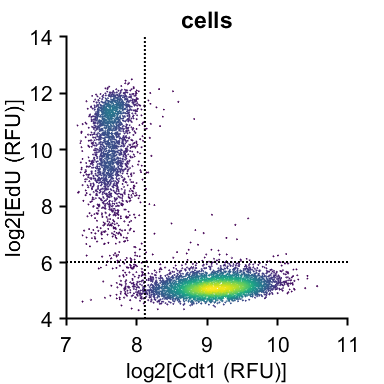

ans = 7486

conds=[1 ];

xval = 'FarRed1';
yval = 'FarRed2';

for i = 1:length(conds)
    condition = conds(i);
    xdata = log2(S(condition).(xval));
    ydata =  log2(S(condition).(yval));
    
    inds = S(condition).dna < 2^20.75  & S(condition).cdk(:,end) > .7  & S(condition).cdk(:,end) < 1.2;
    % inds = S(condition).POI(:,3) > numFrames - 10;
    xdata = xdata(inds);
    ydata = ydata(inds);
%     length(xdata)
%     inds = randsample(length(xdata),1000,false);
%       xdata = xdata(inds);
%     ydata = ydata(inds);
   
    figure('Units', 'Inches', 'Position', [0, 0, 4, 4]), hold on
     colormap('viridis')
    dscatter(xdata,ydata,'MSIZE',3,'MARKER','o');
    % xlim([2 10])
    % ylim([4 14])
    
    ylabel('log2[EdU (RFU)]');
    xlabel('log2[Cdt1 (RFU)]');
    title(conditions{condition,1});
    hline(log2(gate.FarRed2_G1(2)),'k:');
    vline(log2(gate.FarRed1_S(2)),'k:');
    sum(2.^ydata > gate.FarRed2_G1(2) & 2.^xdata > gate.FarRed1_G1(2))/length(xdata)
    crosstab(2.^ydata > gate.FarRed2_G1(2) , 2.^xdata > gate.FarRed1_G1(2))/length(xdata) * 100
    axis square
    print_pdf([pwd() '\Figs\cdt1vsedu.pdf'])
    length(xdata)
end

**Check GMNN vs EdU levels all cells**

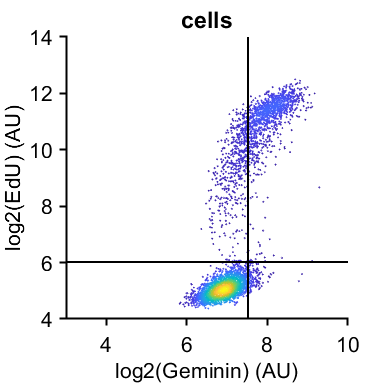

total = 5781

Scells = 182

conds=[1];

xval = 'YFP2';
yval = 'FarRed2';

for i = 1:length(conds)
    condition = conds(i);
    xdata = (log2(S(condition).(xval)));
    ydata =  (log2(S(condition).(yval)));
    %
    % inds = S(condition).dna < 2^21.5;
    inds = S(condition).POI_time(:,1) > 3 & S(condition).POI_time(:,1) < 5;
    xdata = xdata(inds);
    ydata = ydata(inds);
    
    figure('Units', 'Inches', 'Position', [0, 0, 4, 4]), hold on
    dscatter(xdata,ydata,'MSIZE',3,'MARKER','o');
    xlim([3 10])
    ylim([4 14])
    vline(log2(gate.YFP2_G1(2)),'k');
    hline(log2(gate.FarRed2_G1(2)),'k');
    axis square
    ylabel('log2(EdU) (AU)');
    xlabel('log2(Geminin) (AU)');
    title(conditions{condition,1});%h = vline(20.5,'k');v = hline(9,'k');
    axis square
    if condition == 1
        print_pdf([pwd() '\Figs\GMNNvsEdU.pdf'])
        total = length(xdata)
        Scells = sum(xdata<log2(gate.YFP2_G1(2)) & ydata>log2(gate.FarRed1_G1(2)))

    end
end